% This is the CPX1 Matlab Live Script - SIGNAL x2
% This file analyzes the first signal, x2
%
% Note that this was written as a live script, and thus prints values and
% plots to the screen for easy access
% 
% While writing a function would have enabled code to be reused, it was
% determined that the more important factor was easy accessibility to the
% plots, and any function would have required a large number of input
% values
%
% See the other files for the analysis of x3 and x4, the files were
% separated due to the intense memory requirements to display all of the
% plots
%
% Almost all plots have the frequency bins above the time/frequency values,
% as that enabled easy zooming in

% ================ Setup ================ %

cd("C:\Users\C25Dante.Cometto\OneDrive - afacademy.af.edu\Documents\1 Important\3 School 2024F\5 ECE 434\CPX2")
load cpx2.bin -mat
load filter_x1.bin -mat
who


Your variables are:

Fs      Fs_x3   Fs_x4   Fs_x7   Fs_x8   X1      X1db    a       ans     b       color1  color2  color3  color4  color5  den_x1  df1     dt1     f1      fX1     fX1db   fx1     k1      n1      num_x1  t1      x1      x2      x3      x4      x7      x8      



Fs

Fs = 8000



color1 = "#77A890"

color1 = "#77A890"

color2 = "#26503C"

color2 = "#26503C"

color3 = "#F9F5E9"

color3 = "#F9F5E9"

color4 = "#9E816B"

color4 = "#9E816B"

color5 = "#C15441"

color5 = "#C15441"

% For signal x1
x1;
n1 = 0:length(x1)-1;
dt1 = 1/Fs;
t1 = n1*dt1;
X1 = fft(x1);
k1 = n1;
df1 = Fs/length(k1) % Fs/N

df1 = 1.1429

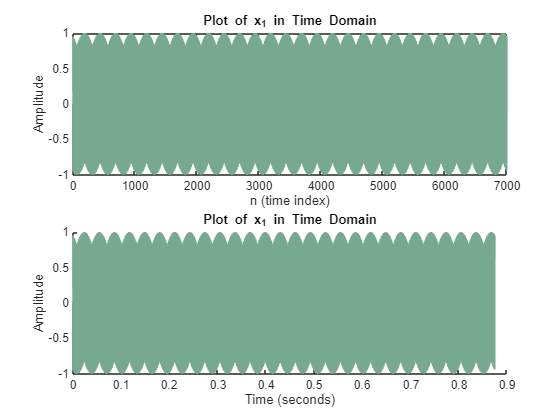

f1 = k1*df1;
X1db = 20*log10(abs(X1)/max(abs(X1)));

% ===== Begin by plotting in time domain =====
figure
subplot(2,1,1)
plot(n1,x1,"Color",color1)
title("Plot of x_1 in Time Domain")
xlabel("n (time index)")
ylabel("Amplitude")

subplot(2,1,2)
hold on
plot(t1,x1,"Color",color1)
title("Plot of x_1 in Time Domain")
xlabel("Time (seconds)")
ylabel("Amplitude")
hold off

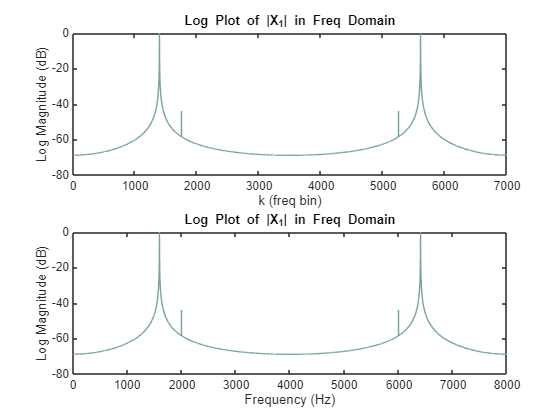


% Zoom in for report!!!

% dB plot
figure
subplot(2,1,1)
plot(k1,X1db,"Color",color1)
title("Log Plot of |X_1| in Freq Domain")
xlabel("k (freq bin)")
ylabel("Log Magnitude (dB)")
subplot(2,1,2)
plot(f1,X1db,"Color",color1)
title("Log Plot of |X_1| in Freq Domain")
xlabel("Frequency (Hz)")
ylabel("Log Magnitude (dB)")


% Zoom in
a = 1350

a = 1350

b = 1800

b = 1800

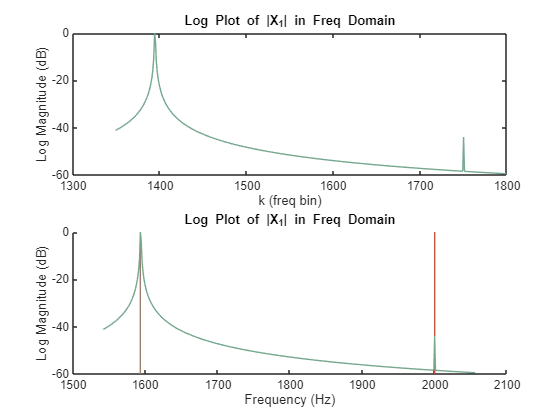


figure
subplot(2,1,1)
plot(k1(a:b),X1db(a:b),"Color",color1)
title("Log Plot of |X_1| in Freq Domain")
xlabel("k (freq bin)")
ylabel("Log Magnitude (dB)")

subplot(2,1,2)
hold on
plot([1593 1593],[-60 0],"Color",color4)
plot([2000 2000],[-60 0],"Color",color5)
plot(f1(a:b),X1db(a:b),"Color",color1)
title("Log Plot of |X_1| in Freq Domain")
xlabel("Frequency (Hz)")
ylabel("Log Magnitude (dB)")

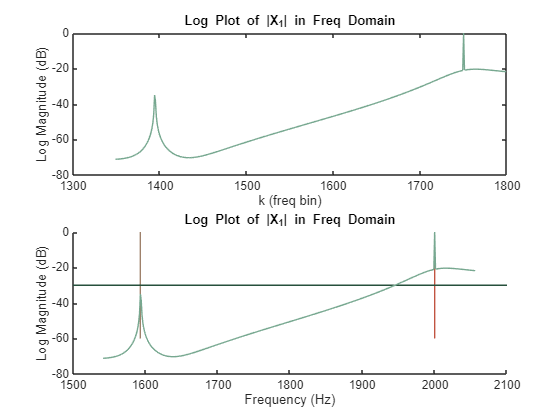


% => Freqs are at 1593 Hz and 2000 Hz

% Now, apply filter

fx1 = filter(num_x1,den_x1,x1);
fX1 = fft(fx1);
fX1db = 20*log10(abs(fX1)/max(abs(fX1)));

% Changelog:
% v1 - just over -30dB, order 7
% v2 - well below -30db, order 7

% And plot again

figure
subplot(2,1,1)
plot(k1(a:b),fX1db(a:b),"Color",color1)
title("Log Plot of |X_1| in Freq Domain")
xlabel("k (freq bin)")
ylabel("Log Magnitude (dB)")

subplot(2,1,2)
hold on
plot([1593 1593],[-60 0],"Color",color4)
plot([2000 2000],[-60 0],"Color",color5)
plot([1500 2100],[-30 -30],"Color",color2)
plot(f1(a:b),fX1db(a:b),"Color",color1)
title("Log Plot of |X_1| in Freq Domain")
xlabel("Frequency (Hz)")
ylabel("Log Magnitude (dB)")